clear
clc
close all

A = [-1 0.1; 0.5 -1]

A =    -1.0000    0.1000
    0.5000   -1.0000


B = [-0.1; 0.1]

B =    -0.1000
    0.1000



R = 1

R = 1

Q = eye(2)

Q =      1     0
     0     1


H = [A -B * R^(-1) * B'; -Q -A'] % Hamiltonian matrix

H =    -1.0000    0.1000   -0.0100    0.0100
    0.5000   -1.0000    0.0100   -0.0100
   -1.0000         0    1.0000   -0.5000
         0   -1.0000   -0.1000    1.0000



eig(H)

ans =    -1.2324
   -0.7754
    0.7754
    1.2324


T = 500; % Terminal time

tspan  = linspace(0, T, 201);

solinit = bvpinit(tspan, @guess);

sol = bvp4c(@odefun, @bcfun, solinit);


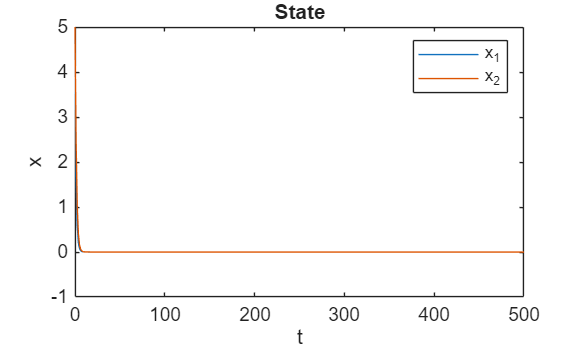

t  = linspace(0, T, 400);

Y  = deval(sol, t);

x  = Y(1:2, :);

la = Y(3:4, :);

u  = -(R\(B')) * la;


figure; plot(t, x); xlabel('t'); ylabel('x'); legend('x_1','x_2'); title('State');

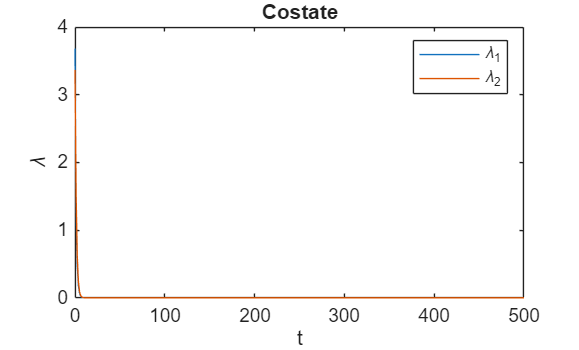

figure; plot(t, la); xlabel('t'); ylabel('\lambda'); legend('\lambda_1','\lambda_2'); title('Costate');

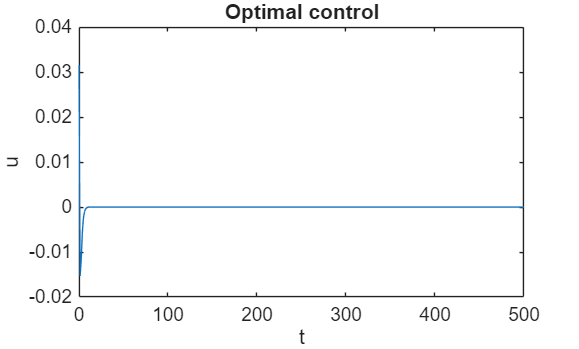

figure; plot(t, u); xlabel('t'); ylabel('u'); title('Optimal control');

function dydx = odefun(t, y)

% y = [x; lambda] = [x(1); x(2); lambda(1); lambda(2)]

A = [-1 0.1; 0.5 -1];
B = [-0.1; 0.1];

R = 1;
Q = eye(2);

H = [A -B * R^(-1) * B'; -Q -A'];

dydx = H * y;

end

function res = bcfun(ya, yb)

% ya = y(0)

% yb = y(T)

x0 = [5; 5];

S = [0 0; 0 0]; % Q_T

res = [ya(1 : 2) - x0; yb(3 : 4) - S * yb(1 : 2)];

end

function y = guess(t)

% Simple decaying guess for x, zero for lambda (works fine for LQR)

x0 = [5; 5];

y = [x0 .* exp(-t); 0; 0];

end